# **Effet d'une arthroplastie totale inversée d'épaule sur les synergies musculaires**

**Analyse synergies**

clc; close all; clear all; %#ok<CLALL>

*Notice d'information sur les muscles étudiés*

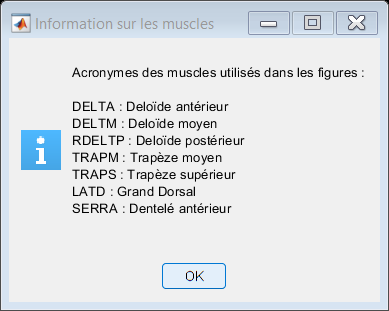

info_message = sprintf(['Acronymes des muscles utilisés dans les figures :\n\n' ... 
'DELTA : Deloïde antérieur\n' ... 
'DELTM : Deloïde moyen\n' ... 
'RDELTP : Deloïde postérieur\n' ... 
'TRAPM : Trapèze moyen\n' ... 
'TRAPS : Trapèze supérieur\n' ... 
'LATD : Grand Dorsal\n' ... 
'SERRA : Dentelé antérieur\n\n']); 
msgbox(info_message, 'Information sur les muscles', 'help');

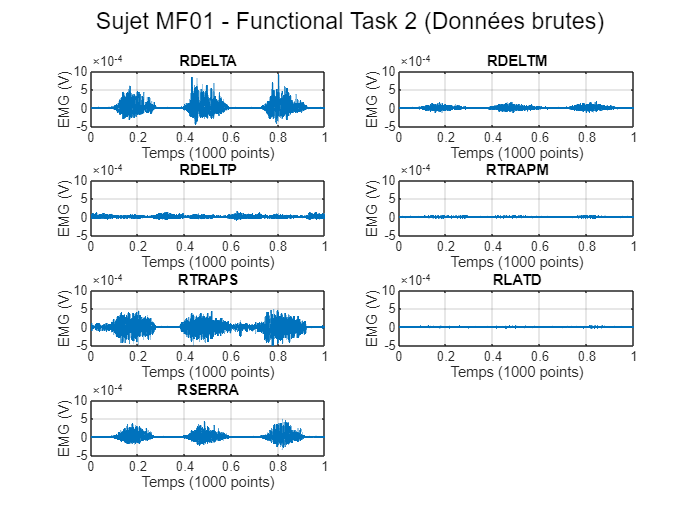

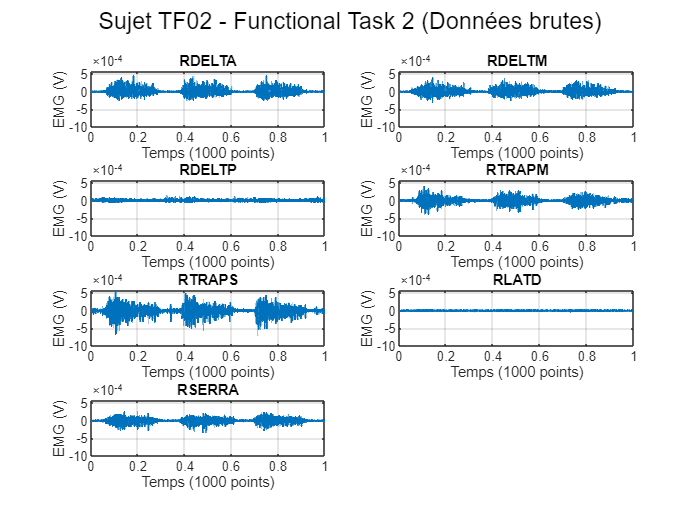

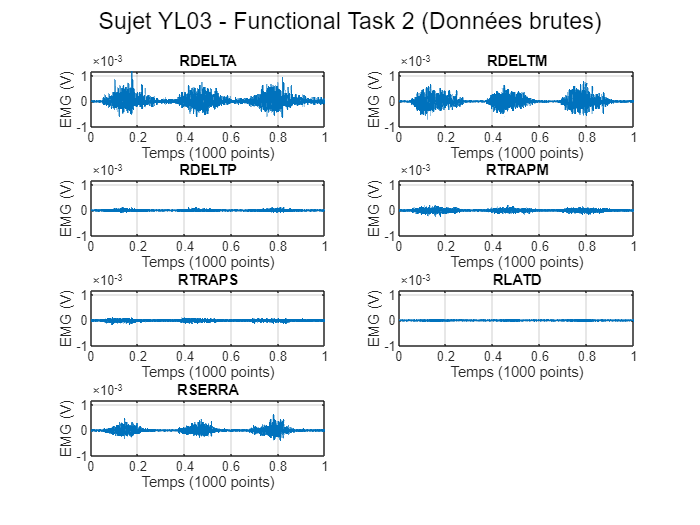

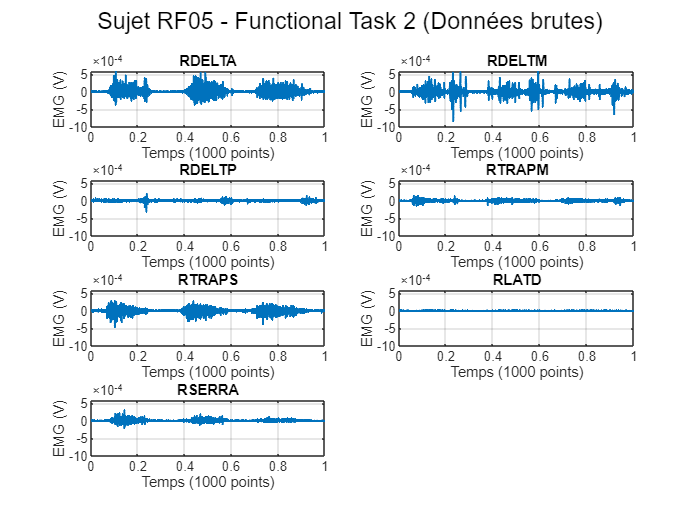

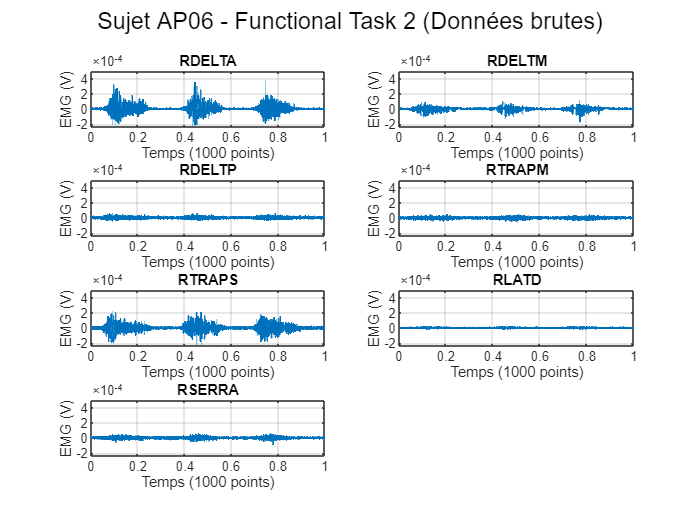

clc; clear all;

% Ajout de la bibliothèque btk
addpath(genpath('C:\Users\Francalanci Hugo\Documents\MATLAB\Stage Sainte-Justine\HUG\btk'));

% Définition des sujets
subjects = {'MF01', 'TF02', 'YL03', 'RF05', 'AP06'};
nb_subjects = length(subjects);

% Définition des muscles 
muscles = {'RDELTA', 'RDELTM', 'RDELTP', 'RTRAPM', 'RTRAPS', 'RLATD', 'RSERRA'};
nb_muscles = length(muscles);

% Définition des labels pour les tâches
functional_labels = {'Functional Task 1', 'Functional Task 2', 'Functional Task 3', 'Functional Task 4'};
analytic_labels = {'Analytic Task 1', 'Analytic Task 2', 'Analytic Task 3', 'Analytic Task 4'};

nb_functional = length(functional_labels);
nb_analytic = length(analytic_labels);

% Sélection de l'analytique et du fonctionnel 
selected_analytic = input('Choisissez une tâche analytique (1-4): ');
selected_functional = input('Choisissez une tâche fonctionnelle (1-4): ');

% Paramètres EMG
fs = 2000;
[b, a] = butter(4, [15, 475] / (fs/2), 'bandpass');
rms_window = round(0.250 * fs);
num_points = 1000;
time_normalized = linspace(0, 1, num_points);

% Initialisation des MVCs
mvc_flexion = zeros(nb_muscles, 1);
all_functional_data = cell(nb_subjects, nb_functional, nb_muscles);

%% **Visualisation des données brutes**
for subj_idx = 1:nb_subjects
    fileName = sprintf(['C:\\Users\\Francalanci Hugo\\Documents\\MATLAB\\Stage Sainte-Justine\\HUG\\Sujets\\%s\\' ...
        '%s-%s-20240101-PROTOCOL01-FUNCTIONAL%d-.c3d'], ...
        subjects{subj_idx}, subjects{subj_idx}, subjects{subj_idx}, selected_functional);

    c3dH = btkReadAcquisition(fileName);
    analogs = btkGetAnalogs(c3dH);
    
    figure;
    sgtitle(sprintf('Sujet %s - %s (Données brutes)', subjects{subj_idx}, functional_labels{selected_functional}));
    
    ax = gobjects(nb_muscles, 1);
    for m = 1:nb_muscles
        ax(m) = subplot(ceil(nb_muscles/2), 2, m);
        muscle_name = muscles{m};
        if isfield(analogs, muscle_name)
            signal = analogs.(muscle_name);
            time_original = linspace(0, 1, length(signal));
            plot(time_original, signal, 'LineWidth', 1.2);
            title(muscle_name);
            xlabel('Temps (1000 points)');
            ylabel('EMG (V)');
            grid on;
        else
            title(sprintf('%s (Données absentes)', muscle_name));
        end
    end
    linkaxes(ax, 'y');
end

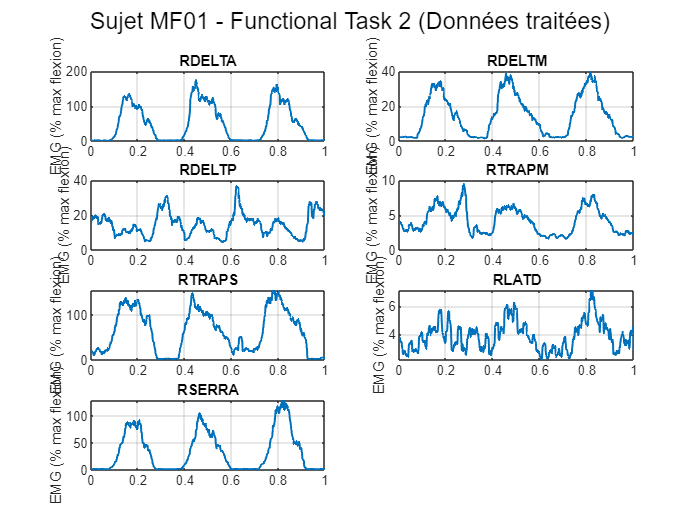

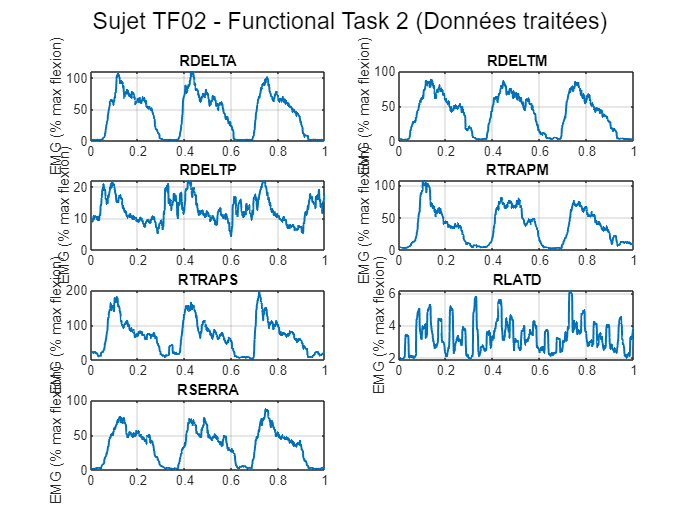

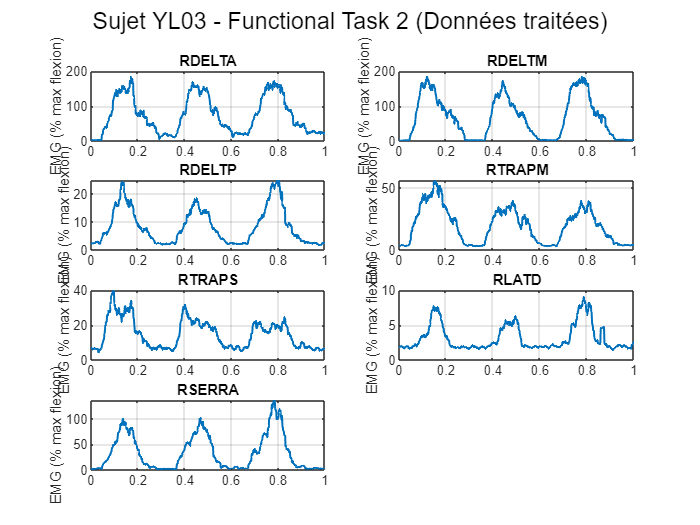

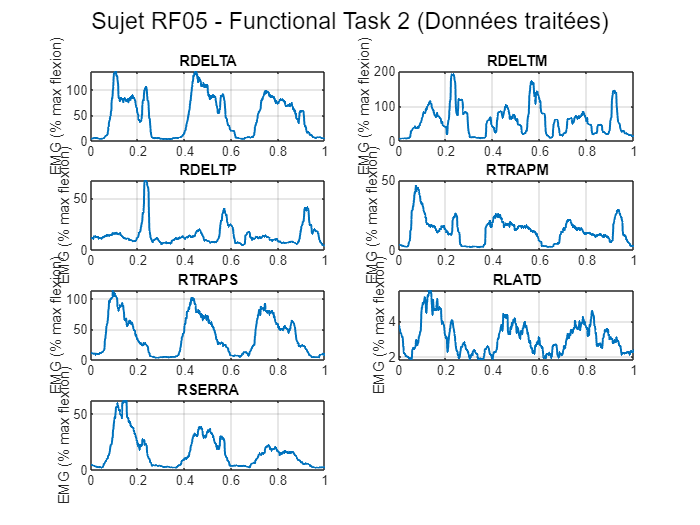

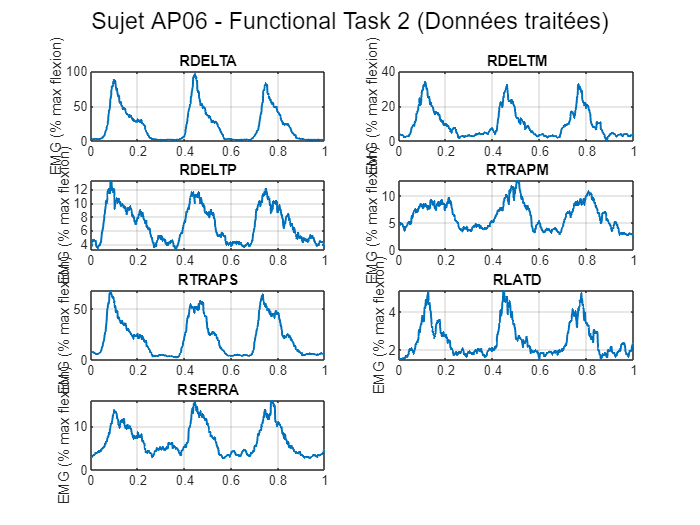


%% **Traitement des tâches analytiques pour calcul des MVC**
for subj_idx = 1:nb_subjects
    fileName_analytic = sprintf(['C:\\Users\\Francalanci Hugo\\Documents\\MATLAB\\Stage Sainte-Justine\\HUG\\Sujets\\%s\\' ...
        '%s-%s-20240101-PROTOCOL01-ANALYTIC%d-.c3d'], ...
        subjects{subj_idx}, subjects{subj_idx}, subjects{subj_idx}, selected_analytic);

    c3dH_analytic = btkReadAcquisition(fileName_analytic);
    analogs_analytic = btkGetAnalogs(c3dH_analytic);

    for m = 1:nb_muscles
        muscle_name = muscles{m};
        if isfield(analogs_analytic, muscle_name)
            signal = analogs_analytic.(muscle_name);

            % Filtrage passe-bande
            signal_filtered = filtfilt(b, a, signal);
            % Rectification
            signal_abs = abs(signal_filtered);
            % Lissage RMS
            emg_rms = sqrt(movmean(signal_abs.^2, rms_window));

            % Stockage du MVC (Max de la tâche sélectionnée)
            mvc_flexion(m) = max(emg_rms);
        end
    end
end

% Normalisation : prendre le MAX des MVC flexion
mvc_max = max(mvc_flexion);

%% **Traitement et normalisation des tâches fonctionnelles**
for subj_idx = 1:nb_subjects
    fileName_functional = sprintf(['C:\\Users\\Francalanci Hugo\\Documents\\MATLAB\\Stage Sainte-Justine\\HUG\\Sujets\\%s\\' ...
        '%s-%s-20240101-PROTOCOL01-FUNCTIONAL%d-.c3d'], ...
        subjects{subj_idx}, subjects{subj_idx}, subjects{subj_idx}, selected_functional);

    c3dH_functional = btkReadAcquisition(fileName_functional);
    analogs_functional = btkGetAnalogs(c3dH_functional);

    figure;
    sgtitle(sprintf('Sujet %s - %s (Données traitées)', subjects{subj_idx}, functional_labels{selected_functional}));

    for m = 1:nb_muscles
        subplot(ceil(nb_muscles/2), 2, m);
        muscle_name = muscles{m};
        if isfield(analogs_functional, muscle_name)
            signal = analogs_functional.(muscle_name);
            time_original = linspace(0, 1, length(signal));

            % Filtrage passe-bande
            signal_filtered = filtfilt(b, a, signal);
            % Rectification
            signal_abs = abs(signal_filtered);
            % Lissage avec Root Mean Square
            emg_rms = sqrt(movmean(signal_abs.^2, rms_window));

            % Normalisation par le MAX des MVCs des tâches analytiques
            if mvc_max ~= 0
                emg_normalized = (emg_rms / mvc_max) * 100;
            else
                emg_normalized = emg_rms; % Si aucun MVC dispo, on garde les valeurs non normalisées
            end

            % Interpolation sur l'axe temporel normalisé
            interp_signal_functional = interp1(time_original, emg_normalized, time_normalized, 'spline');

            all_functional_data{subj_idx, selected_functional, m} = interp_signal_functional;

            % Affichage des données fonctionnelles traitées
            plot(time_normalized, interp_signal_functional, 'LineWidth', 1.2);
            title(muscle_name);
            ylabel('EMG (% max flexion)');
            grid on;
        else
            title(sprintf('%s (Données absentes)', muscle_name));
        end
    end
end

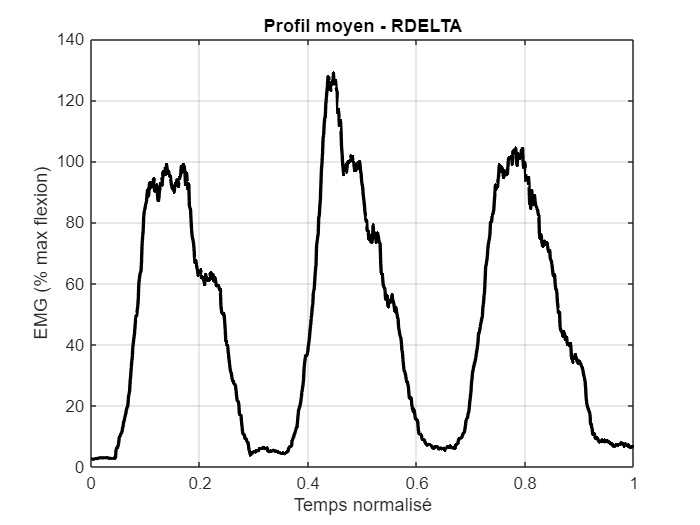

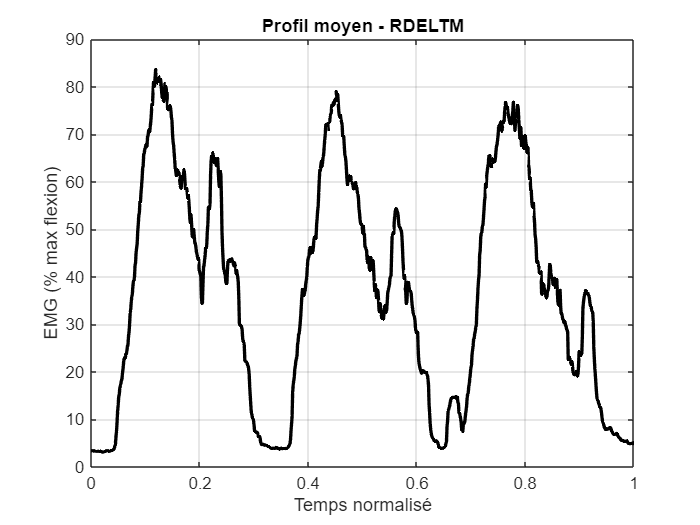

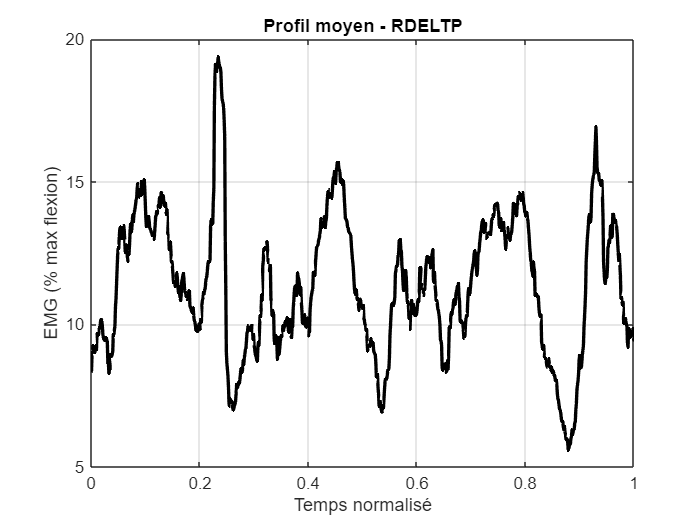

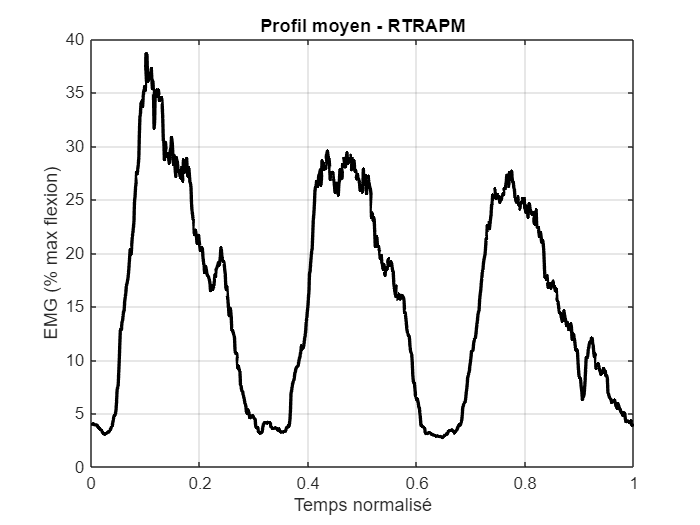

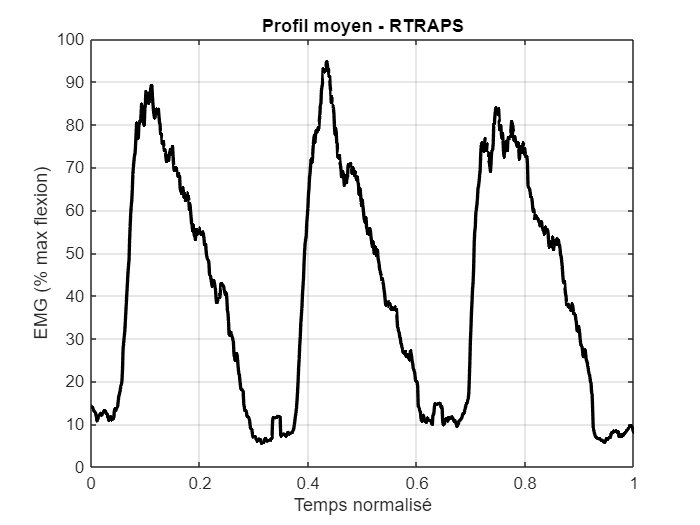

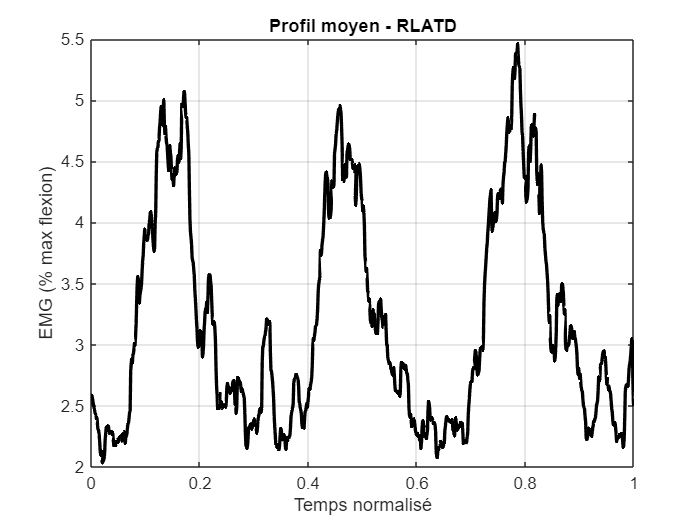

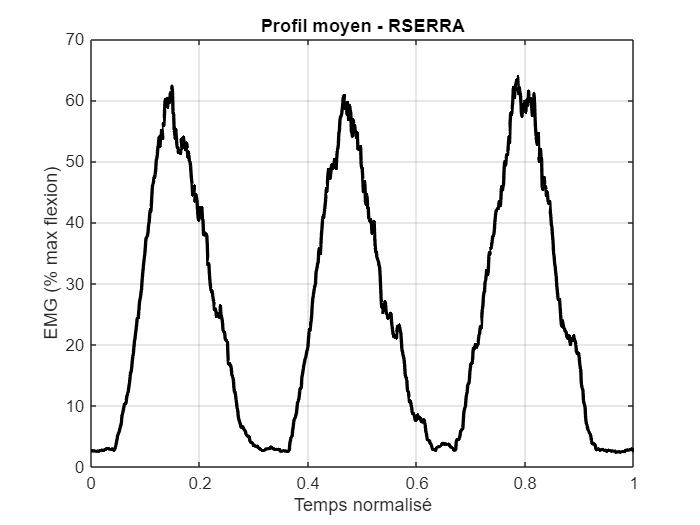


%% **Comparaison inter-sujets et calcul de la moyenne**
mean_functional_data = zeros(nb_muscles, num_points);
subject_count_per_muscle = zeros(nb_muscles, 1);

for m = 1:nb_muscles
    all_subjects_matrix = NaN(nb_subjects, num_points);

    for subj_idx = 1:nb_subjects
        if ~isempty(all_functional_data{subj_idx, selected_functional, m})
            all_subjects_matrix(subj_idx, :) = all_functional_data{subj_idx, selected_functional, m};
        end
    end
    
    % Calcul de la moyenne en ignorant les NaN
    mean_profile = nanmean(all_subjects_matrix, 1);
    
    % Vérification si la moyenne est valide (pas entièrement NaN)
    if ~all(isnan(mean_profile))
        mean_functional_data(m, :) = mean_profile;
        subject_count_per_muscle(m) = sum(~isnan(all_subjects_matrix(:, 1)));
    end
    
    % Affichage des courbes moyennes
    figure;
    plot(time_normalized, mean_profile, 'k', 'LineWidth', 2);
    title(sprintf('Profil moyen - %s', muscles{m}));
    xlabel('Temps normalisé');
    ylabel('EMG (% max flexion)');
    grid on;
end


%% **Calcul des synergies musculaires sur la moyenne des sujets**
% Vérification de la présence de données valides avant NNMF
if all(mean_functional_data(:) == 0)
    error('Aucune donnée valide pour la tâche %s.', functional_labels{selected_functional});
end

% Paramètres NNMF
max_synergies = min(10, nb_muscles);
VAF_threshold = 0.90;
VAF_values = zeros(1, max_synergies);
optimal_synergies = max_synergies;
foundOptimal = false;

% Options NNMF
options = statset('MaxIter', 1000, 'Display', 'off');

% Boucle pour estimer le VAF et déterminer le nombre optimal de synergies
for s = 1:max_synergies
    [W, H] = nnmf(mean_functional_data, s, 'Options', options);
    X_reconstructed = W * H;
    VAF_values(s) = 1 - sum((mean_functional_data(:) - X_reconstructed(:)).^2) / sum(mean_functional_data(:).^2);
    
    if VAF_values(s) >= VAF_threshold && ~foundOptimal
        optimal_synergies = s;
        foundOptimal = true;
    end
end


% Affichage des résultats
fprintf('Nombre optimal de synergies pour la tâche %s : %d (VAF = %.2f%%)\n', ...
    functional_labels{selected_functional}, optimal_synergies, VAF_values(optimal_synergies) * 100);

Nombre optimal de synergies pour la tâche Functional Task 2 : 1 (VAF = 97.55%)


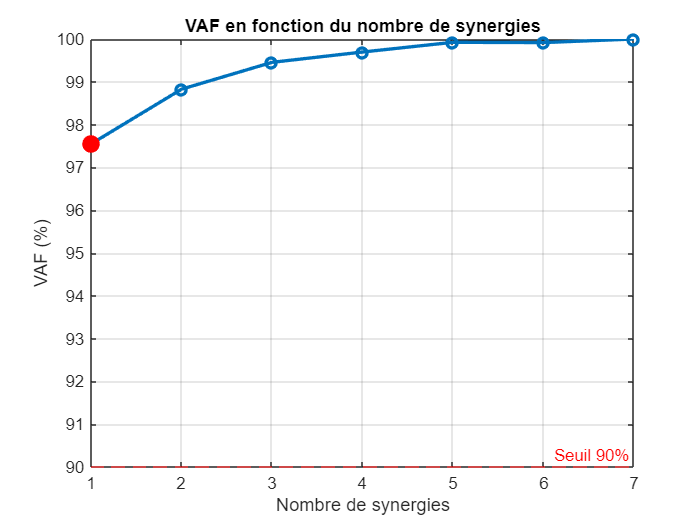


% Tracé du VAF en fonction du nombre de synergies
figure;
plot(1:max_synergies, VAF_values * 100, '-o', 'LineWidth', 2);
hold on;
yline(VAF_threshold * 100, 'r--', 'Seuil 90%');
plot(optimal_synergies, VAF_values(optimal_synergies) * 100, 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
xlabel('Nombre de synergies');
ylabel('VAF (%)');
title('VAF en fonction du nombre de synergies');
grid on;

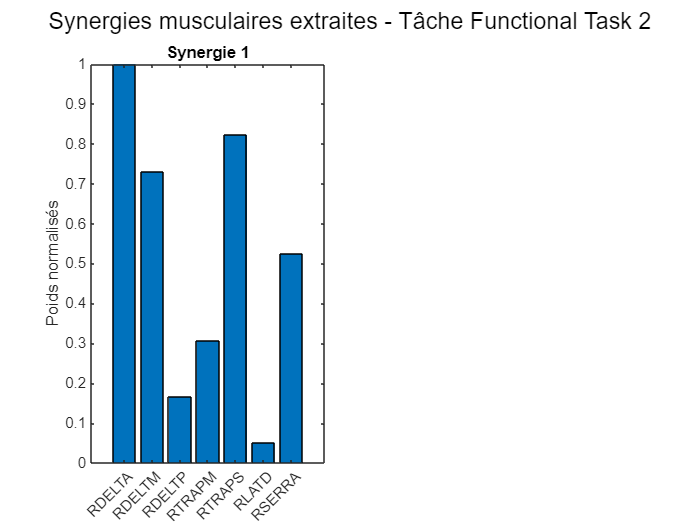


%% **Visualisation des synergies musculaires extraites**
[W, H] = nnmf(mean_functional_data, optimal_synergies, 'Options', options);
W_norm = W ./ max(W, [], 1);

figure;
sgtitle(sprintf('Synergies musculaires extraites - Tâche %s', functional_labels{selected_functional}));
for i = 1:optimal_synergies
    subplot(ceil(optimal_synergies / 2), 2, i);
    bar(W_norm(:, i), 'FaceColor', 'flat');
    title(['Synergie ', num2str(i)]);
    xticks(1:nb_muscles);
    xticklabels(muscles);
    xtickangle(45);
    ylabel('Poids normalisés');
end

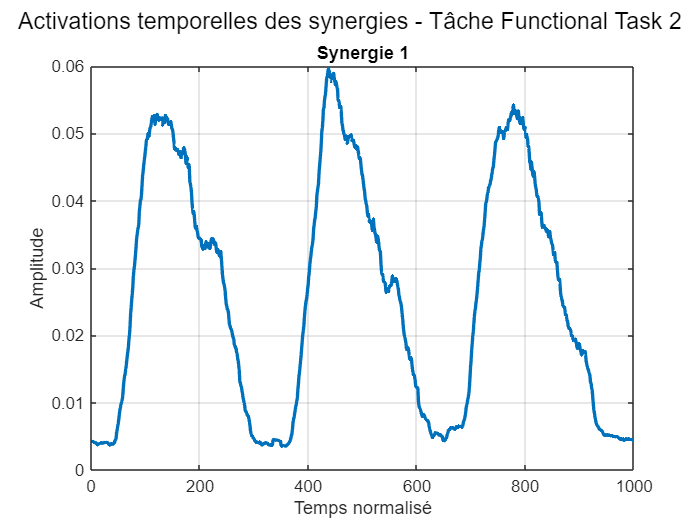


%% **Visualisation des activations temporelles des synergies**
figure;
sgtitle(sprintf('Activations temporelles des synergies - Tâche %s', functional_labels{selected_functional}));
for i = 1:optimal_synergies
    subplot(optimal_synergies, 1, i);
    plot(H(i, :), 'LineWidth', 2);
    title(['Synergie ', num2str(i)]);
    grid on;
end
xlabel('Temps normalisé');
ylabel('Amplitude');